eegSignal = EEGdata;
fs = 512; % Sampling frequency of the EEG signal (in Hz)
t = (0:length(eegSignal)-1)/fs; % Time vector
% Baseline correction
baselineWindow = [0 1]; % Define the time window for baseline correction (in seconds)
baselineIndices = t >= baselineWindow(1) & t <= baselineWindow(2);
baseline = mean(eegSignal(baselineIndices));
correctedSignal = eegSignal - baseline;
figure;
% Plot the original EEG signal
subplot(2,1,1);
plot(t, eegSignal);
title('Original EEG Signal');
xlabel('Time (s)');
ylabel('Amplitude');
% Plot the baseline-corrected EEG signal
subplot(2,1,2);
plot(t, correctedSignal);
title('Baseline-Corrected EEG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

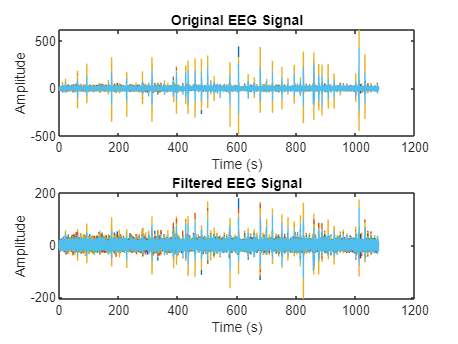

% EEG Signal Bandpass filter
% Load and plot the EEG signal
eegsignal= correctedSignal;
fs = 512; % Sampling frequency of the EEG signal
t = 0:(length(eegsignal)-1); % Time vector
t = t/fs;
% the bandpass filter parameter
fpass = [0.2 30]; % passband frequencies
order = 4; % Filter order
% Design the filter
[b, a] = butter(order, fpass/(fs/2), 'bandpass');
% Apply filter to EEG signal
filteredSignal = filtfilt(b, a, eegsignal);
% Plot the original and filtered signals
% Plot the original signal
figure;
subplot(2,1,1);
plot(t, eegsignal);
title('Original EEG Signal');
xlabel('Time (s)');
ylabel('Amplitude');
% Plot the filtered signal
subplot(2,1,2);
plot(t, filteredSignal);
title('Filtered EEG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

eegsignal = filteredSignal;

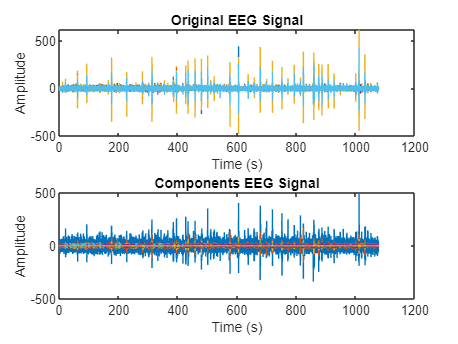

n = length(eegsignal); % number of samples
% Center the data by subtracting the mean from each feature
centeredData = eegsignal - repmat(mean(eegsignal),n,1); 
% Calculate the covariance matrix
covarianceMatrix = cov(centeredData);
% Perform eigendecomposition of the covariance matrix
[eigenVectors, eigenValues] = eig(covarianceMatrix);
% Sort eigenvalues and eigenvectors in descending order
[eigenValues, sortedIndices] = sort(diag(eigenValues), 'descend');
eigenVectors = eigenVectors(:, sortedIndices); 
% Determine the cumulative explained variance
% explainedVariance = cumsum(eigenValues) / sum(eigenValues);
% Select the desired number of principal components based on the explained variance threshold
% explainedVarianceThreshold = 0.95; % Change this 
% value as desired
% numComponents = find(explainedVariance >= explainedVarianceThreshold, 1);
% Project the data onto the selected principal components
projectedData = centeredData * eigenVectors(:, 1:10);
subplot(2,1,2);
plot(t, projectedData);
title('Components EEG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

eegsignal = projectedData;

AverageValue  = mean(eegsignal, "all")

AverageValue = -1.9474e-17

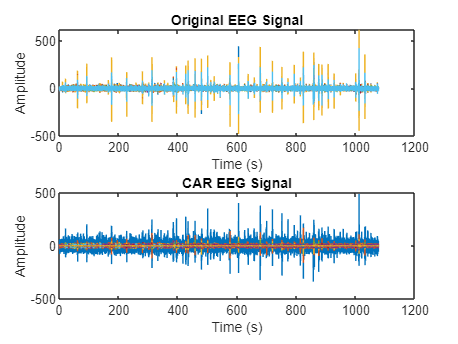

CARdata = eegsignal - AverageValue;
subplot(2,1,2);
plot(t, CARdata);
title('CAR EEG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

eegsignal = CARdata;

MetricMatrix = []


MetricMatrix =

     []



for n = 1:length(trial)
    Epoch = eegsignal(trial(n) + fs*3 : trial(n) + fs*8, :);
    Epoch_mean = mean(Epoch, "all");
    Epoch_max = max(max(Epoch));
    Epoch_std = std(Epoch, 1, "all");
    Epoch_rms = rms(Epoch, "all");
    MetricMatrix(n, 1) = Epoch_mean;
    MetricMatrix(n, 2) = Epoch_std;
    MetricMatrix(n, 3) = Epoch_max;
    MetricMatrix(n, 4) = Epoch_rms;
end
% Below just some tryings with LDA, let's continue in google collab with
% Logistic Regression

% % Calculate the number of training entries...
% train_off = round(length(MetricMatrix) * 0.8);
% 
% % Split data into training and test vectors...
% train = MetricMatrix(1:train_off, :);
% test = MetricMatrix(train_off+1:end, :);
% 
% % Calculate the number of training entries...
% train_off2 = round(length(label) * 0.8);
% 
% % Split data into training and test vectors...
% train_lab = label(1:train_off, :);
% test_lab = label(train_off+1:end, :);

% %add label to metricmatrix and separate for 2 classes
% newmatrix = MetricMatrix;
% newmatrix(:, 3) = label

newmatrix =     0.1922   10.7480    2.0000
   -0.0700    9.7404    1.0000
   -0.1163    7.9513    2.0000
    0.1367   10.0189    2.0000
    0.1962   13.4111    1.0000
    0.1453   11.0421    1.0000
   -0.0125    9.7498    2.0000
    0.0911   13.6038    2.0000
   -0.3902   10.0149    2.0000
    0.0829    9.9177    1.0000


% newmatrix = sortrows(newmatrix,3)

newmatrix =    -0.0700    9.7404    1.0000
    0.1962   13.4111    1.0000
    0.1453   11.0421    1.0000
    0.0829    9.9177    1.0000
   -0.0175    9.9069    1.0000
    0.1681   10.6843    1.0000
   -0.1449   14.8565    1.0000
   -0.1705   10.3910    1.0000
   -0.2087    9.6523    1.0000
   -0.0900   10.9247    1.0000


% for n=1:length(newmatrix)
%     if newmatrix(n, 3) == 2
%         class1 = (newmatrix(1:n-1, 1:2));
%         class2 = (newmatrix(n:length(newmatrix), 1:2));
%         y = newmatrix(:, 3);
%         break
%     end
% end

B =     0.6559
    0.0082


% % Sample input data 
% % class1=[4 2 ;2 4 ;2 3 ;3 6 ;4 4 ];
% % class2=[9 10 ;6 8 ;9 5 ;8 7 ;10 8 ];
% % % Concatenate the input data
% X= [class1; class2];
% % class label
% %y = [1; 1; 1; 1; 1; 2; 2; 2; 2; 2];
% %1. Calculate the means of each class
% mu1 = mean(X(y == 1, :));
% mu2 = mean(X(y == 2, :));
% %2. Calculate the covariance matrices
% cov1 = cov(X(y == 1, :));
% cov2 = cov(X(y == 2, :));
% %3. Calculate the within-class scatter matrix
% Sw = cov1 + cov2;
% %4. Calculate the between-class scatter matrix
% Sb = (mu1 - mu2)' * (mu1 - mu2);
% %5. Calculate the eigenvalues and eigenvectors
% [eigenvecs, eigenvals] = eig(inv(Sw) * Sb);
% %6. Sort the eigenvalues in descending order
% [~, idx] = sort(diag(eigenvals), 'descend');
% %7. Select the largest eigenvalue and corresponding eigenvector
% W = eigenvecs(:, idx(1));
% % Project the data onto the linear discriminant
% X_lda = X * W;
% % Plot the projected data
% plot(X_lda(y == 1), zeros(sum(y == 1), 1), 'ro')
% hold on
% plot(X_lda(y == 2), zeros(sum(y == 2), 1), 'bo')
% title('Linear Discriminant Analysis');
% xlabel('Projected Data');
% ylabel('Class');
% legend('Class 1', 'Class 2');